class1 = 'TURMER';
class2 = 'LUSMEG';
bandEdges = linspace(50,22050,42);

directoryPath = sprintf('samples/%s/syllables/%s',class1,"train");
syllableFileList = dir(fullfile(directoryPath, '*.wav'));
syllableFileNames = {syllableFileList.name};
limit = 100;
mfccMatrix = {};
chunkSize = 2;
for id = class1Ids
    pattern = ['^', id, '_\d+\.wav$'];
    matchingSyllableFilenames = syllableFileNames(~cellfun(@isempty, regexp(syllableFileNames, pattern)));
    numChunks = ceil(length(matchingSyllableFilenames) / chunkSize);
end

ans = 1×39 cell array
    {1×0 char}    {'XC786387'}    {'XC787340'}    {'XC787580'}    {'XC788737'}    {'XC789456'}    {'XC789663'}    {'XC790089'}    {'XC792322'}    {'XC792833'}    {'XC792991'}    {'XC793567'}    {'XC793995'}    {'XC794140'}    {'XC794897'}    {'XC797183'}    {'XC798129'}    {'XC798913'}    {'XC800820'}    {'XC801227'}    {'XC803007'}    {'XC805288'}    {'XC806072'}    {'XC808753'}    {'XC809767'}    {'XC810355'}    {'XC811347'}    {'XC812846'}    {'XC812861'}    {'XC813685'}    {'XC813901'}    {'XC814307'}    {'XC815262'}    {'XC815527'}    {'XC815529'}    {'XC815531'}    {'XC815857'}    {'XC817459'}    {'XC818144'}


chunkSize = 2;
trainTestSplit = 0.75;
maxLengthS = 60;
directoryPath = sprintf('samples/%s/raw',class1);
filesWav = dir(fullfile(directoryPath, '*.wav'));
filesMp3 = dir(fullfile(directoryPath, '*.mp3'));
allFiles = [filesWav; filesMp3];
fileNames = {allFiles.name};
totalSamples = numel(fileNames);
numTrainSamples = round(totalSamples*trainTestSplit);
trainIndices = randperm(totalSamples,numTrainSamples);
testIndices = setdiff(1:totalSamples,trainIndices);
f = waitbar(0,'Starting syllable segmentation...');
TURMER_mfccTrain = {};
TURMER_mfccTest = {};
for ii = 1:totalSamples
    filename = sprintf('samples/%s/raw/%s',class1,fileNames{ii});
    progress = ii / numel(fileNames);
    waitbar(progress,f,sprintf('Segmenting file %s',filename));
    [audio, fs] = audioread(filename);
    audio = mono(audio);
    audio = stripSound(audio,fs,500);
    maxLength = maxLengthS*fs;
    if numel(audio) > maxLength
        audio = audio(1:maxLength);
    end
    syllables = segmentSyllables(audio,fs);
    for jj = 1:3:length(syllables)
        if jj+2 > length(syllables)
            break
        end
        combinedSyllable = [syllables{jj};syllables{jj+1};syllables{jj+2}];
        if length(combinedSyllable) < round(fs*0.03)
            continue
        end
        mfccFeature = mfcc(combinedSyllable,fs,"BandEdges",bandEdges);
        if ismember(ii,trainIndices)
            TURMER_mfccTrain = [TURMER_mfccTrain;{mfccFeature'}];
        else
            TURMER_mfccTest = [TURMER_mfccTest;{mfccFeature'}];
        end
    end
end
close(f);

directoryPath = sprintf('samples/%s/raw',class2);
filesWav = dir(fullfile(directoryPath, '*.wav'));
filesMp3 = dir(fullfile(directoryPath, '*.mp3'));
allFiles = [filesWav; filesMp3];
fileNames = {allFiles.name};
totalSamples = numel(fileNames);
numTrainSamples = round(totalSamples*trainTestSplit);
trainIndices = randperm(totalSamples,numTrainSamples);
testIndices = setdiff(1:totalSamples,trainIndices);
f = waitbar(0,'Starting syllable segmentation...');
LUSMEG_mfccTrain = {};
LUSMEG_mfccTest = {};
for ii = 1:totalSamples
    filename = sprintf('samples/%s/raw/%s',class2,fileNames{ii});
    progress = ii / numel(fileNames);
    waitbar(progress,f,sprintf('Segmenting file %s',filename));
    [audio, fs] = audioread(filename);
    audio = mono(audio);
    audio = stripSound(audio,fs,500);
    maxLength = maxLengthS*fs;
    if numel(audio) > maxLength
        audio = audio(1:maxLength);
    end
    syllables = segmentSyllables(audio,fs);
    for jj = 1:3:length(syllables)
        if jj+2 > length(syllables)
            break
        end
        combinedSyllable = [syllables{jj};syllables{jj+1};syllables{jj+2}];
        if length(combinedSyllable) < round(fs*0.03)
            continue
        end
        mfccFeature = mfcc(combinedSyllable,fs,"BandEdges",bandEdges);
        if ismember(ii,trainIndices)
            LUSMEG_mfccTrain = [LUSMEG_mfccTrain;{mfccFeature'}];
        else
            LUSMEG_mfccTest = [LUSMEG_mfccTest;{mfccFeature'}];
        end
    end
end
close(f);

XTrain = [TURMER_mfccTrain;LUSMEG_mfccTrain];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_mfccTrain,1)) = -1;
YTrain = categorical(YTrain, [-1, 1], {class1,class2});

validIds = cellfun(@(x) size(x, 2) <= 100, XTrain);
XTrain = XTrain(validIds);
YTrain = YTrain(validIds);

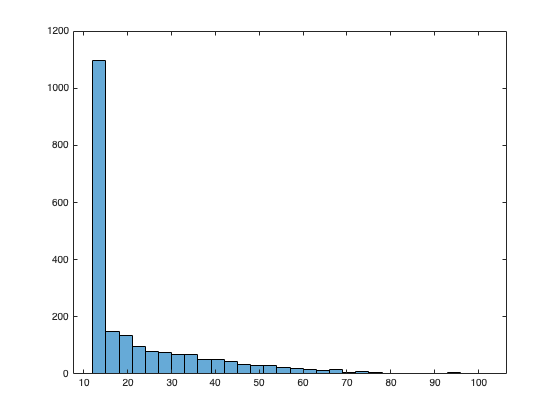

L = cellfun(@length,XTrain);
h = histogram(L);

XTest = [TURMER_mfccTest;LUSMEG_mfccTest];
YTest = ones(size(XTest,1),1);
YTest(1:size(TURMER_mfccTest,1)) = -1;
YTest = categorical(YTest, [-1, 1], {class1,class2});
validIds = cellfun(@(x) size(x, 2) <= 100, XTest);
XTest = XTest(validIds);
YTest = YTest(validIds);

numObservations = numel(XTrain);
for i=1:numObservations
    sequence = XTrain{i};
    sequenceLengths(i) = size(sequence,2);
end

[sequenceLengths,idx] = sort(sequenceLengths);
XTrain = XTrain(idx);
YTrain = YTrain(idx);

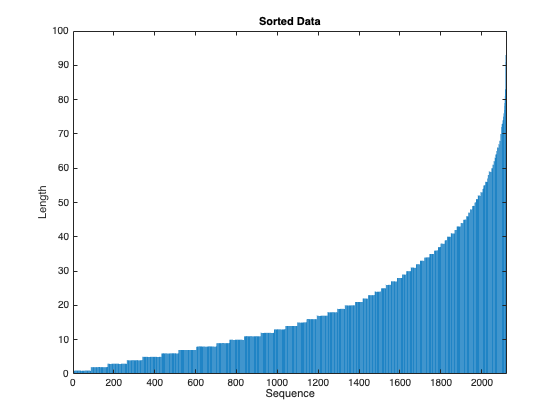

figure
bar(sequenceLengths)
xlabel("Sequence")
ylabel("Length")
title("Sorted Data")

[XTrain,YTrain,XVal,YVal] = createValidationSplit(XTrain,YTrain);

inputSize = 14;
numHiddenUnits = 200;
numClasses = 2;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   5×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 14 dimensions
     2   ''   BiLSTM                  BiLSTM with 200 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

miniBatchSize = 150;
options = trainingOptions("adam", ...
    ExecutionEnvironment="cpu", ...
    GradientThreshold=1, ...
    MaxEpochs=100, ...
    MiniBatchSize=miniBatchSize, ...
    SequenceLength="longest", ...
    ValidationData={XVal,YVal}, ...
    Shuffle="never", ...
    Verbose=0, ...
    Plots="training-progress");

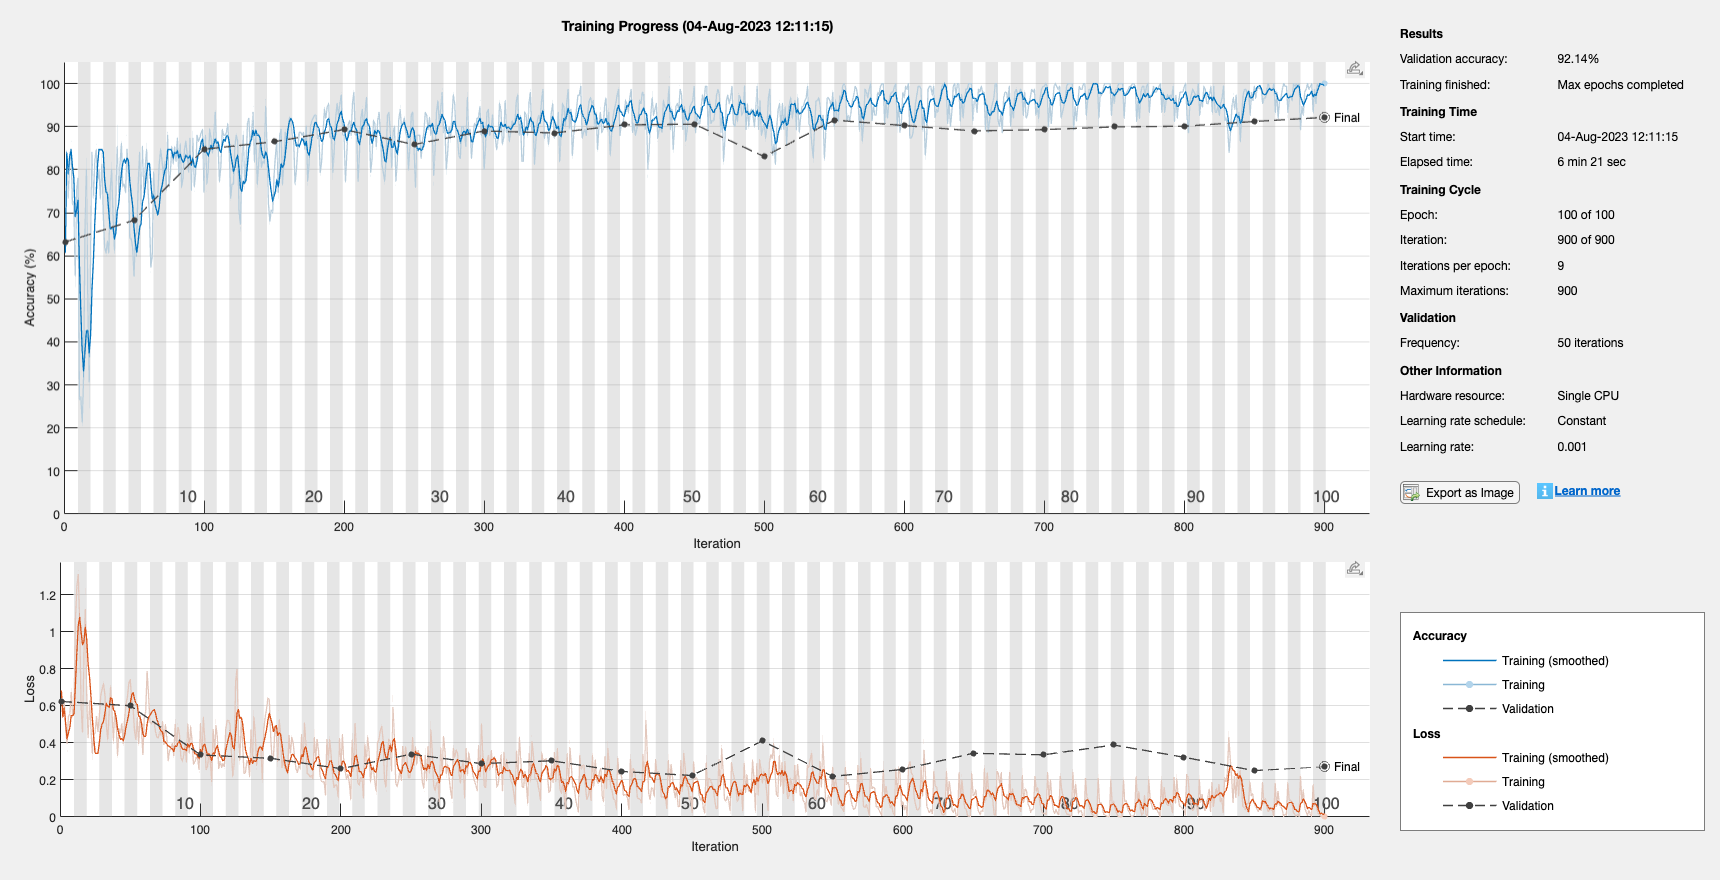

net2 = trainNetwork(XTrain,YTrain,layers,options);

numObservationsTest = numel(XTest);
for i=1:numObservationsTest
    sequence = XTest{i};
    sequenceLengthsTest(i) = size(sequence,2);
end

[sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
XTest = XTest(idx);
YTest = YTest(idx);

YPred = classify(net2,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequenceLength="longest");

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.7711

numFeatures = 14;
filterSize = 3;
numFilters = 32;

layers = [ ...
    sequenceInputLayer(numFeatures)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    reluLayer
    layerNormalizationLayer
    globalAveragePooling1dLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=150, ...
    SequencePaddingDirection="left", ...
    ValidationData={XVal,YVal}, ...
    Plots="training-progress", ...
    Verbose=0);

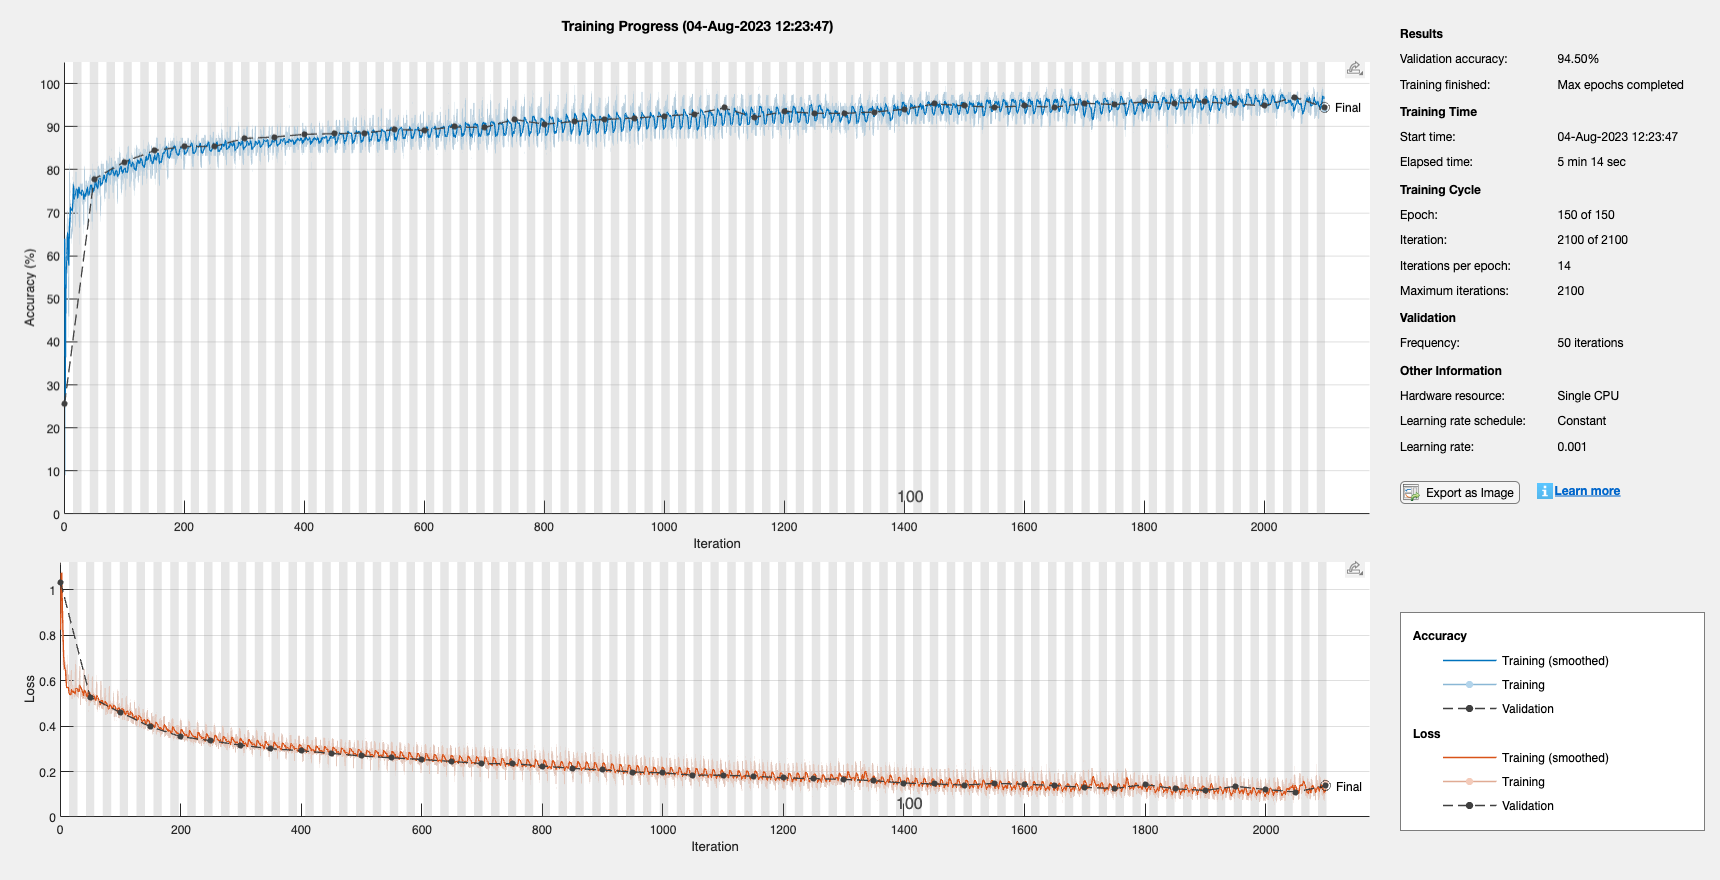

mfccCNNNet = trainNetwork(XTrain,YTrain,layers,options);

YPred = classify(mfccCNNNet,XTest, ...
    MiniBatchSize=miniBatchSize, ...
    SequencePaddingDirection="left");

acc = mean(YPred == YTest)

acc = 0.8553

function birdIDs = getUniqueFilenames(birdType)
directoryPath = sprintf('samples/%s/raw',birdType);
fileList = dir(directoryPath);
filenames = {fileList(~[fileList.isdir]).name};
[~, filenames, ~] = cellfun(@fileparts, filenames, 'UniformOutput', false);
birdIDs = unique(filenames);
end